## clean up and add path

clear
close all
clc
addpath(genpath('..\..'))%% reach the functions and filters

## path data generation

dt = 0.1;
vx = 1;
vy = 0;

x_c = 0;
y_c = 7;

i = 1;
while x_c <10
    path(i,:) = [x_c, y_c];
    x_c = x_c + vx*dt;
    y_c = y_c + vy*dt + randn*0.1;
    i = i + 1;
end

## doing smoothing while reading sensor

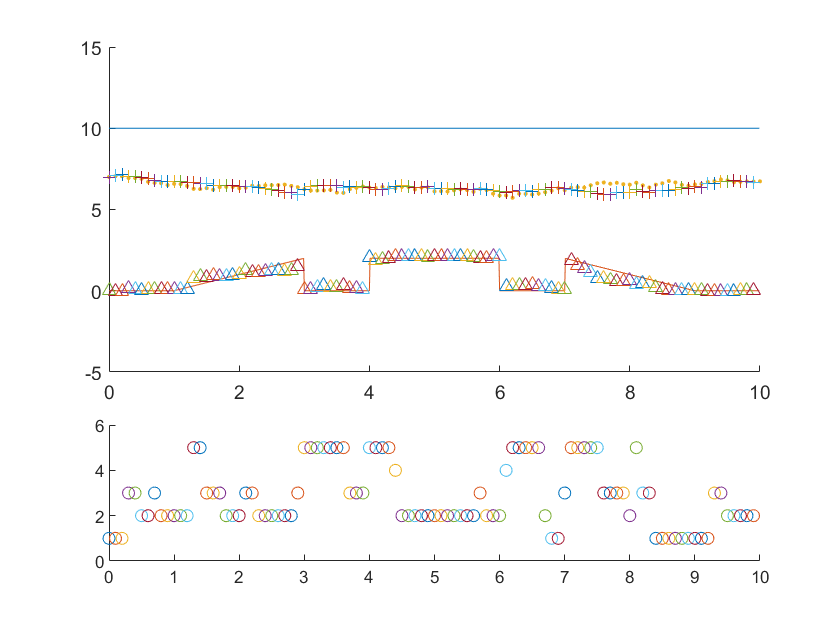

% define the environment
s = sensors(@roof,@terran,path);
% define the filter

if 1
    M = 100; % number of particles
    x0 = [ones([M,1])*7,ones([M,1])*0]; % initial states
    modeln = 5;
    RndTrs = cell([modeln, 1]);
    for modeli = 1:modeln
        eval(['RndTrs{', num2str(modeli), '} = @RndTr', num2str(modeli), ';'])
    end
    filter = PfBsMM(x0,RndTrs,@LiOb);
    filter.rho = 0.5;
else
    filter = FilterAverage();
    filter.set_threshold(0.3);
    filter.set_correctionC(0.01);
end
% filtering loop

figure
subplot(3,1,1:2)
s.plot()
hold on
while s.hasNext()
    [d, x_c] = s.read();
    y = d.infrareddown;
    x_hat = filter.estimate(y); % doing filtering
    subplot(3,1,1:2)
    plot(x_c, x_hat(1),'+')
    try
        plot(x_c, x_hat(2),'^')
        ylim([-5,15])
        
        m_ind = 1:modeln;
        subplot(3,1,3)
        hold on
        plot(x_c, m_ind(filter.MW==max(filter.MW)), 'o')
    catch
    end
end

# discussions

## combining  models

The observation model is very obvious, and there is not much to talk about it.

There are 2 kinds of state transitions models:

- self coordinated, focus on the change of the states

- world coordinated, focus on the absolute value of the states

While we are estimating 3 states with only the differences are observed. It is impossible to remove the accumulated error with the 1st kind of transition alone. However, utilizing the history states can give a better estimation. The best result is achieved by combining the two kinds.

## sensors

Even though the ceil has more obsticals, I still suggest a sensor upward. Bad measure is still informative. My suggestion is to use a wild angle ultrasound sensor upward it still increase the height estimation if the model takes randomness into consideration.

# Model functions

## room description function

function y = roof(x)
y = 10*ones(size(x));
end
function y = terran(x)
y = zeros(size(x));
y(x>1 & x<3) = (x(x>1 & x<3)-1);
y(x>4 & x<6) = 2;
y(x>7 & x<9) = -(x(x>7 & x<9)-9);
end

## model

## ovservation

$y$: downward distance measure

## **states**

$x_1$: height of the drone

$x_2$: displacement of roof, upward

$x_3$: displacement of terrain, downward

## observation model


$$y = x_1 - x_3 +\epsilon_2,\ 
\epsilon_2 \sim \mathcal{N}(0,\sigma_1^2)$$


## observarion likelihood function

input:

y: 1*Dy: one observation, Dy=1

x: N*Dx: N state vectors, Dx=2

output:

p: N*1: likelihood vector

function p = LiOb(y,x)
% observation likelihood

% parameter
sig = 0.1;
% calculate the likelihood saperately
p = normpdf(x(:,1) - x(:,2), y, sig);
end

## Transition model

for all the following functions:

input:

x: N*Dx: N state vectors, Dx=2

randomOn: 0 or 1

    if 0, returns prediction without noise

    if 1, returns noisy transition states

output:

x: same as input

## model1: no obstical at all


$$x_1 = x_1 + \epsilon\\
x_{2} = 0$$


function x = RndTr1(x,randomOn)
% state ransition function 1
% keep the same
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2) = 0;
end

## model2: keep the same


$$x_1 = x_1 + \epsilon\\
x_2 = x_2$$


function x = RndTr2(x,randomOn)
% state ransition function 1
% keep the same
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
end

## model3: random walk


$$x_1 = x_1 + \epsilon_1\\
x_{2} = x_{2} + \epsilon_2$$


function x = RndTr3(x,randomOn)
% state ransition function 2
% random walk
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
sig_wall = 0.1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2) = x(:,2) + randn(size(x(:,2)))*sig_wall*randomOn;
end

## model4: uniform 


$$x_1 = x_1 + \epsilon\\
x_2 = \mathcal{U}(r2)$$


function x = RndTr4(x,randomOn)
% state ransition function 1
% uniform
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
rangedown = [-1,5];
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2) = ( rand(size(x(:,2))) * range(rangedown) + min(rangedown))*randomOn;
end

## model5: exp obsticles 


$$x_1 = x_1 + \epsilon\\
x_2 \sim Ex(\mu2)$$


function x = RndTr5(x,randomOn)
% state ransition function 1
% uniform
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
mudown = 1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2) = exprnd(mudown,size(x(:,2)))*randomOn;
end

## Mixture model

function x = RndTr(x,randomOn)
% mixture model
% mixture weights
w = [0,3,1,6,2];
if nargin == 1
    randomOn = 1;
end
model = datasample(1:5,1,'weights',w );
eval(['x = RndTr',num2str(model),'(x,randomOn);'])
end
